# Diseño de reactores químicos en continuo

Autor(a): Paloma Barajas Álvarez, Tecnólogico de Monterrey

## Resumen

*En esta actividad, los estudiantes trabajarán con modelos de reactores químicos de flujo continuo, específicamente CSTR (Continuous Stirred Tank Reactor) y PFR (Plug Flow Reactor), aplicando conceptos de balances molares y cinética química. Resolveran ecuaciones diferenciales ordinarias que describen la evolución de las concentraciones de los reactivos y productos en los reactores y compararán el comportamiento de los dos tipos de reactores, entendiendo la importancia de parámetros como la velocidad de reacción o el flujo en la formación de productos. *

## Objetivos de Aprendizaje

Al finalizar la actividad los estudiantes serán capaces de plantear los balances molares de reactivos y productos en reactores PFR y CSTR para reacciones irreversibles simples. Resolverán ecuaciones diferenciales ordinarias de los reactores utilizando Matlab y obtendrán gráficas de concentraciones o flujos molares de cada especie. Finalmente, analizarán la influencia de variables clave, como la velocidad de reacción y el flujo volumétrico, sobre la concentración de reactivos y productos. 

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Sección 1: Reactor continuo de tanque agitado (CSTR) 

El reactor continuo de tanque agitado (CSTR por sus siglas en ingles: Continuous Stirred Tank Reactor), es un reactor químicio ideal que se utiliza principalmente para reacciones en **fase líquida**. Normalmente se opera en estado estacionario y se asume que esta **perfectamente mezclado, **se asume que el contenido del tanque está perfectamente mezclado, por lo que la composición y temperatura son uniformes en todo el reactor y en la corriente de salida. Otra de las características del reactor es que los productos generados salen de manera continua, manteniendo el volumen constante.

En este sentido, el balance molar para este tipo de reactor consiste en: 


$$F_{\textrm{j0}} -F_j +\int^V r_j \textrm{dV}=\frac{dN_j }{\textrm{dt}}$$


Al considerarse que opera en estado estacionario: 


$$\frac{dN_j }{\textrm{dt}}=0$$


Se considera que es perfectamente mezclado


$$\int^V r_j \textrm{dV}=r_j V$$


La ecuación de diseño del CSTR proporciona el volumen del reactor *V* necesario para reducir el flujo molar de entrada de la especie *j* desde $F_{\textrm{j0}}$ hasta el flujo molar de salida $F_j$, cuando la especie *j* está desapareciendo a una velocidad de ${-r}_j$.


$$V=\frac{F_{\textrm{j0}} -F_j }{-r_j }$$


Las ventajes del reactor CSTR son: 

- Operación continua y estable

- Control sencillo de temperatura y condiciones de operación

- Fácil de escalar a nivel industrial

Las desventajas son: 

- Conversión más baja que en reactores de flujo pistón (PFR) para el mismo volumen, ya que siempre se alimenta con reactivos diluidos por la mezcla.

- Requiere mayor volumen que un PFR para alcanzar la misma conversión.

Para ejemplificar el comportamiento de este reactor realiza la siguiente actividad: 

Simular en un reactor de tanque agitado la reacción 


$$A\to B$$


Se determinará la manera en cómo varían los moles de A y B dentro del reactor en el tiempo, considerando los flujos molares de entrada y salida y la velocidad de reacción dependiente de la concentración.

El reactor tiene las siguientes condiciones: 

- Flujo molar de entrada de A: $F_{\textrm{A0}} =5\;\frac{\textrm{mol}}{\min }$

- Flujo volumétrico: $v=10\;\frac{L}{\min }$

- Volumen del reactor: $V=50\;L$

- Constante cinética: $k=0\ldotp 1\;\frac{1}{\min }$

- Condiciones iniciales dentro del reactor: $N_A =0\;\textrm{mol}$ y $N_B =0\;\textrm{mol}$  

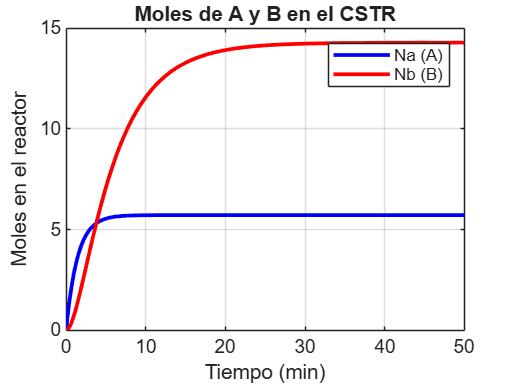

    clc; close all;

    % Parámetros del reactor
    Fa0 = 4;        % mol/min, flujo de entrada de A
    v = 10;         % L/min, caudal volumétrico
    V = 50;         % L, volumen constante del reactor
    k = 0.5;        % 1/min, constante cinética

    % Condiciones iniciales
    Na0 = 0;  % moles de A
    Nb0 = 0;  % moles de B
    N0 = [Na0 Nb0];

    % Tiempo de simulación
    tspan = [0 50];

    % Resolver ODEs
    [t, N] = ode45(@(t,N) balanceCSTR(t,N,Fa0,v,V,k), tspan, N0);

    % Extraer resultados
    Na = N(:,1);
    Nb = N(:,2);


    % ===== Graficar moles de A y B =====
    figure
    plot(t, Na, 'b-', 'LineWidth', 2); hold on;
    plot(t, Nb, 'r-', 'LineWidth', 2);
    xlabel('Tiempo (min)');
    ylabel('Moles en el reactor');
    legend('Na (A)', 'Nb (B)');
    title('Moles de A y B en el CSTR');
    grid on;


% ===== Función que define las EDOs del CSTR =====
function dNdt = balanceCSTR(~, N, Fa0, v, V, k)
    Na = N(1);  % moles de A
    Nb = N(2);  % moles de B

    % Concentraciones instantáneas
    Ca = Na / V;

    % Flujos de salida
    Fa = Ca * v;

    % Velocidad de reacción (A -> B)
    ra = -k * Ca;

    % Balances molares
    dNa = Fa0 - Fa + ra * V;     % balance de A
    dNb = -ra * V - (Nb / V) * v; % balance de B (formación - salida)

    dNdt = [dNa; dNb];
end

## Sección 2: Reactor tubular (PFR)

El reactor de flujo tampón (Plug flow reactor) es un reactor químico que consiste en un tubo cilindrico y normalmente operado en estado estacionario. Es muy utilizado para reacciones en fase gas. En este tipo de reactor los reactivos se consumen continuamente a medida que fluyen a lo largo del reactor, así mismo se asume que la concentración varía de manera continua en la dirección axial a lo largo del reactor. El campo de flujo puede modelarse mediante un perfil de flujo tipo "plug-flow" (velocidad radial uniforme).

En este sentido, el balance molar de *j* para este tipo de reactor consiste en: 


$$F_j |_V -F_j |_{V+\Delta V} +\int^V \textrm{dV}=\frac{dN_j }{\textrm{dt}}$$



$$\int^{\Delta V} r_j \textrm{dV}=r_j \Delta V$$


Entonces: 


$$r_j =\frac{F_j |_V -F_j |_{V+\Delta V} }{\Delta V}$$



$$\frac{\textrm{df}}{\textrm{dx}}=\lim_{\Delta x\to 0} \frac{f\left(x+\Delta x\right)-f\left(x\right)}{\Delta x}$$



$$r_j =\frac{dF_j }{\textrm{dV}}$$


En donde $F_j$ es el flujo molar de la especie *j*, *V* es el volumen del reactor y $r_j$es la velocidad reacción de la especie *j.*

Si se conoce el flujo volumétrico constante $\nu$: 


$$C_j =\frac{F_j }{\nu }$$


Para ejemplificar el comportamiento de este reactor realiza la siguiente actividad: 

Simular en un reactor PFR de acuerdo con la siguiente reacción irreversible: 


$$A\to B+2C$$


- Constante cinética *k* = 0.044 $\frac{1}{\min }$

- Flujo molar de A al inicio: $F_{\textrm{A0}} =2\ldotp 5\;\frac{\textrm{mol}}{s}$

- Flujo volumétrico: $v=10\;\frac{L}{\min }$

Al ser una reacción irreversible los balances de flujos serían:


$$\frac{dF_A }{\textrm{dV}}=-r_A =-k\frac{F_A }{\nu }$$



$$\frac{dF_B }{\textrm{dV}}=+r_A =+k\frac{F_A }{\nu }$$



$$\frac{dF_C }{\textrm{dV}}=+2r_A =+2k\frac{F_A }{\nu }$$


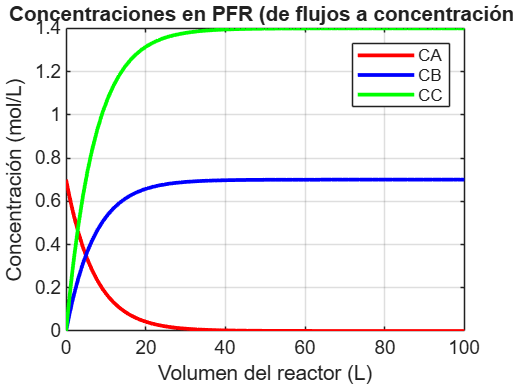

clear; clc; close all;

% --- Parámetros ---
k =1.4;       % 1/min
v = 10;        % L/min, flujo volumétrico constante
Fa0 = 7;       % mol/min, flujo de entrada de A
Vspan = [0 100]; % L, volumen del reactor

% Condiciones iniciales [FA, FB, FC]
F0 = [Fa0, 0, 0];

% Resolver ODE
[V,F] = ode45(@(V,F) balances_flujos(V,F,k,v), Vspan, F0);

% Convertir a concentraciones
Ca = F(:,1)/v;
Cb = F(:,2)/v;
Cc = F(:,3)/v;

% Graficar
figure
plot(V,Ca,'-r','LineWidth',2); hold on
plot(V,Cb,'-b','LineWidth',2)
plot(V,Cc,'-g','LineWidth',2)
xlabel('Volumen del reactor (L)')
ylabel('Concentración (mol/L)')
legend('CA','CB','CC')
title('Concentraciones en PFR (de flujos a concentración)')
grid on


% --- Función de balances en flujos ---
function dF = balances_flujos(~,F,k,v)
    FA = F(1);
    FB = F(2);
    FC = F(3);

    % Velocidad de reacción en términos de concentración
    ra = k * (FA/v);

    % Balances diferenciales en flujos
    dFA = -ra;
    dFB = +ra;
    dFC = +2*ra;

    dF = [dFA; dFB; dFC];
end

## Sección 3: Preguntas de reflexión

- Ejecuta los códigos del CSTR y del PFR con los parámetros dados.

- Genera las gráficas solicitadas (concentraciones, flujos molares o moles en el reactor según el caso).

- Copia en un documento en formato **PDF.**

- Breve introducción (máx. ½ cuartilla) describiendo el objetivo de la simulación.

- Las gráficas obtenidas con una interpretación inicial (¿qué muestran?, ¿cómo cambian las especies?).

- Respuestas a las **preguntas de reflexión**.

- Conclusiones generales (relación entre los dos tipos de reactores).

Completa las siguientes preguntas tomando en cuenta los resultados observados: 

- ¿Cuál de los dos reactores (CSTR o PFR) alcanza mayor conversión bajo las condiciones dadas?

- ¿Cómo cambia el comportamiento del CSTR si la constante cinética k aumenta o disminuye un orden de magnitud? Ejecuta el reactor CSTR con un valor de k = 0.7 y k =0.2. ¿Se observan efectos similares en el PFR?

- Si el objetivo es maximizar la producción de B, ¿qué reactor elegirías?

## Referencias 

Fogler, H. S., García, R. L. E., & Solís, J. F. R. (2008). *Elementos de ingeniería de las reacciones químicas* (pp. 1120-1120). México: Pearson educación.